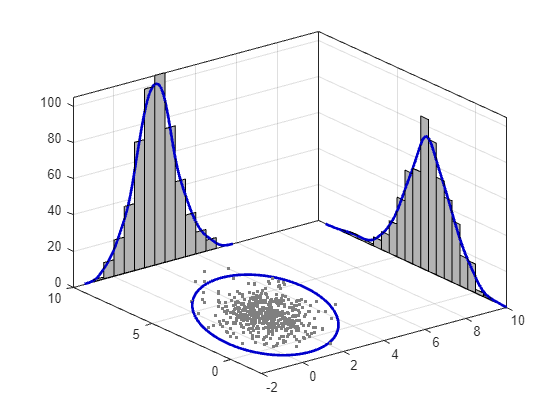

% densityDemo
pntSet=mvnrnd([2 3],[1 .5;.5 2],500);
scatter(pntSet(:,1),pntSet(:,2),40,'.','MarkerEdgeColor',[.5,.5,.5]);

% 计算中心点，协方差矩阵
Mu=mean(pntSet);
Y=pntSet-repmat(Mu,size(pntSet,1),1);
Sigma=cov(Y);
% Sigma=(Y'*(ones(size(pntSet,1),1).*Y))./(size(pntSet,1)-1);

ax=gca;view(3)
hold on;box on;grid on
ax.XLim=[-2,10];
ax.YLim=[-2,10];
%ax.DataAspectRatio=[1,1,1];

% 绘制置信椭圆
[X,Y]=getEllipse(Mu,Sigma,9.21,100);
plot(X,Y,'Color',[0,0,.8],'LineWidth',2);

% 绘制直方图
H1Hdl=histogram(pntSet(:,1));
for i=1:length(H1Hdl.Values)
    fill3([H1Hdl.BinEdges([i,i+1,i+1,i])],[1,1,1,1].*ax.YLim(2),...
        [0,0,H1Hdl.Values([i,i])],[.7,.7,.7])
end
H2Hdl=histogram(pntSet(:,2));
for i=1:length(H2Hdl.Values)
    fill3([1,1,1,1].*ax.XLim(2),[H2Hdl.BinEdges([i,i+1,i+1,i])],...
        [0,0,H2Hdl.Values([i,i])],[.7,.7,.7])
end

ax.ZLim=[0,max([H1Hdl.Values,H2Hdl.Values])];

% 绘制核密度曲线
[f,xi]=ksdensity(pntSet(:,1)); 
plot3(xi,ones(size(xi)).*ax.YLim(2),f.*size(pntSet,1).*H1Hdl.BinWidth,'Color',[0,0,.8],'LineWidth',2)
[f,yi]=ksdensity(pntSet(:,2)); 
plot3(ones(size(yi)).*ax.XLim(2),yi,f.*size(pntSet,1).*H2Hdl.BinWidth,'Color',[0,0,.8],'LineWidth',2)

delete(H1Hdl)
delete(H2Hdl)


% 置信椭圆定位函数

function [X,Y]=getEllipse(Mu,Sigma,S,pntNum)
% 置信区间 | 95%:5.991  99%:9.21  90%:4.605
% (X-Mu)*inv(Sigma)*(X-Mu)=S

invSig=inv(Sigma);

[V,D]=eig(invSig);
aa=sqrt(S/D(1));
bb=sqrt(S/D(4));

t=linspace(0,2*pi,pntNum);
XY=V*[aa*cos(t);bb*sin(t)];
X=(XY(1,:)+Mu(1))';
Y=(XY(2,:)+Mu(2))';
end